时间范围

clc, clear,close all;
load(sprintf('data/data_%d.mat',1));
t = 0:1/f_s:0.01-1/f_s;  

 提取0.01秒的数据

ext_ref = seq_ref(1:0.01*f_s);
ext_sur = seq_sur(1:0.01*f_s);


绘制原信号的时域图像

 ext_ref (原信号)的时域图像

figure;
subplot(2, 1, 1);
plot(t*10^3,ext_ref);

title('Reference signal (raw)');
xlabel('t (ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);

 ext_sur（原信号）的时域图像

subplot(2, 1, 2);
plot(t*10^3, ext_sur);

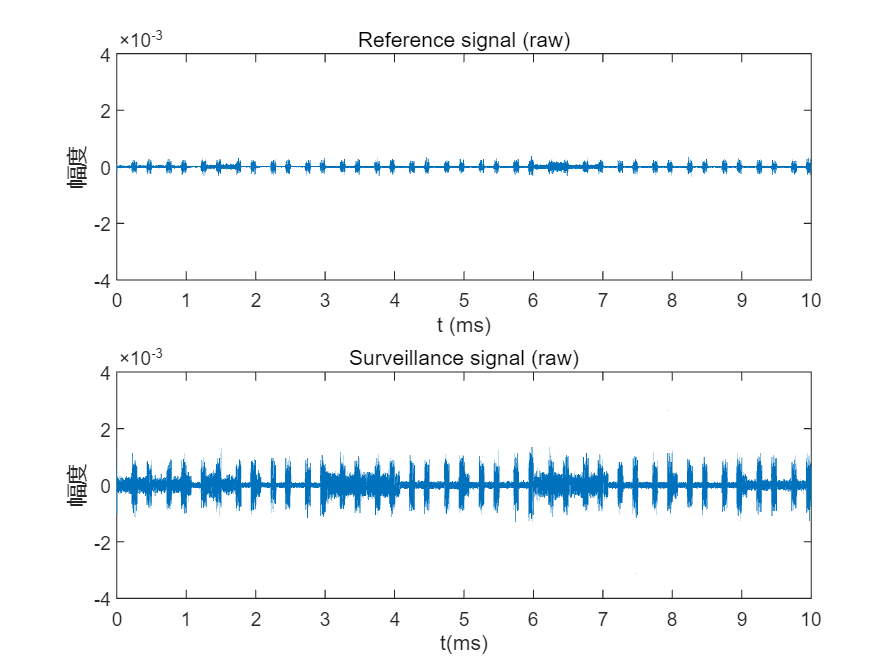

title('Surveillance signal (raw)');
xlabel('t(ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);

绘制原信号的频域函数

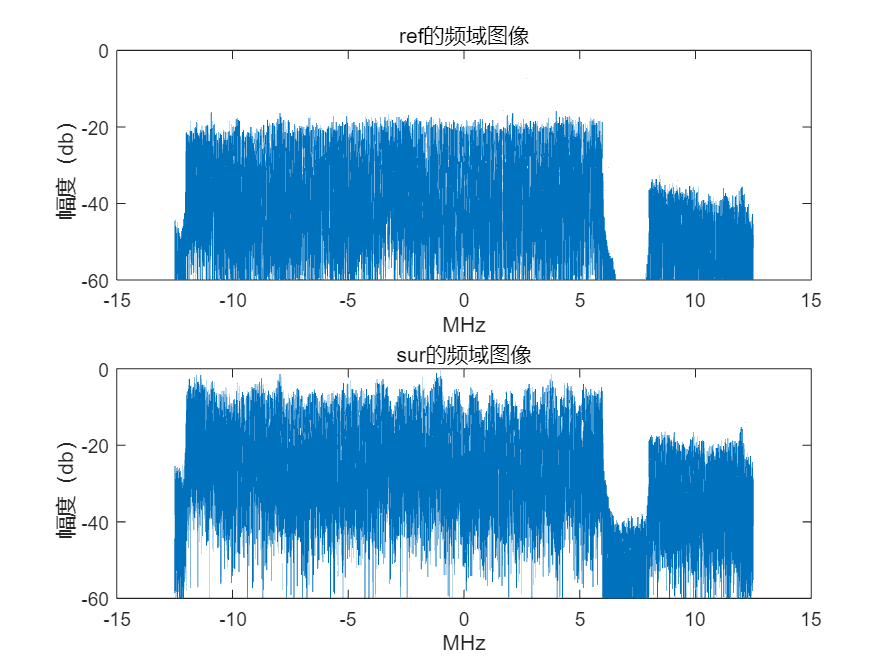

fft_ref = fft(ext_ref);
fft_sur = fft(ext_sur);
N = length(fft(ext_ref));
%频谱横坐标
f1 = (-(N-1)/2:(N-1)/2)*f_s/(N*10^6);
%频谱纵坐标
magnitude_ref=20 * log10(abs(fft_ref));
magnitude_sur=20 * log10(abs(fft_sur));
fftshift_magnitude_ref = fftshift(20 * log10(abs(fft_ref)));
fftshift_magnitude_sur = fftshift(20 * log10(abs(fft_sur)));
figure;
subplot(2,1,1)
plot(f1,fftshift_magnitude_ref);
ylim([-60 0]);
title('ref的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

subplot(2,1,2)
plot(f1,fftshift_magnitude_sur);
ylim([-60 0]);
title('sur的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

f_fftshift = (-N/2:N/2-1) * f_s/N;
f2 = f_fftshift + 3*10^6;

%频移
f_ddc=3e6;
ref_shift=ext_ref.*exp(1i*2*pi*f_ddc*(0:1:length(ext_ref)-1)/f_s);
sur_shift=ext_sur.*exp(1i*2*pi*f_ddc*(0:1:length(ext_ref)-1)/f_s);

% 绘制频移后的时域图像
figure;
subplot(2, 1, 1);
plot(t*10^3,ref_shift);

title('频移后ref的时域图像');
xlabel('t (ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);

 ext_sur（原信号）的时域图像

subplot(2, 1, 2);
plot(t*10^3, sur_shift);

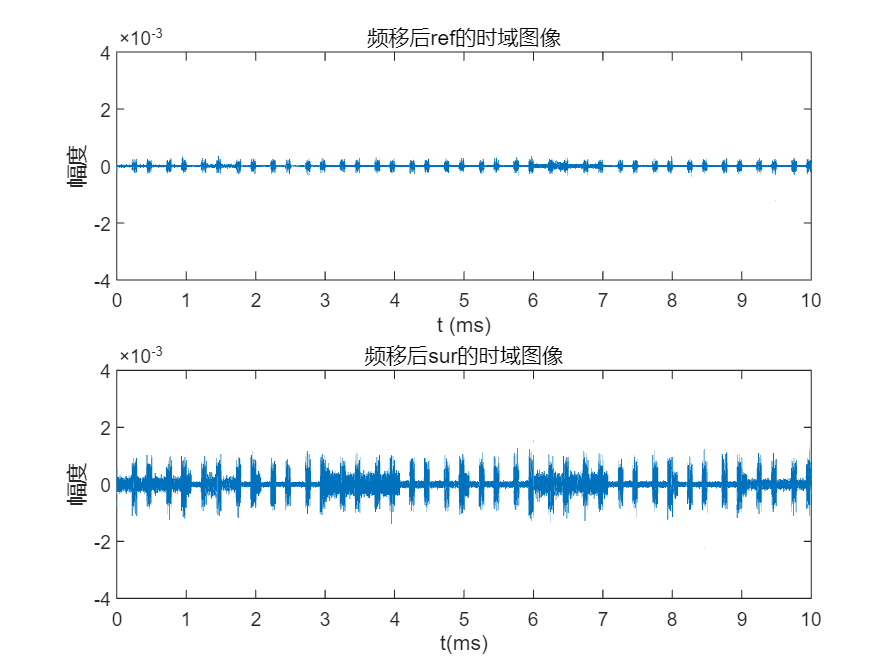

title('频移后sur的时域图像');
xlabel('t(ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);

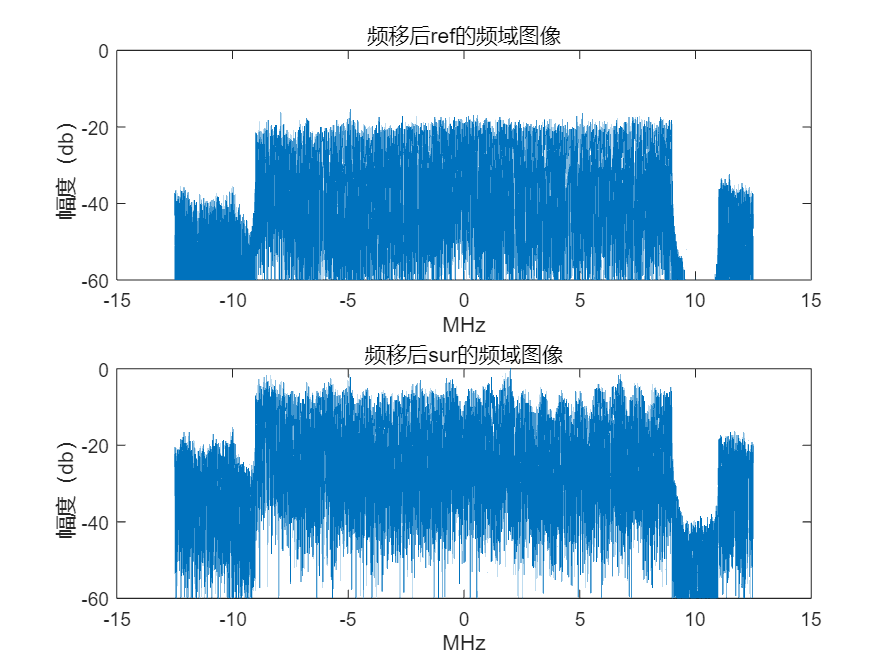



fft_ref = fft(ref_shift);
fft_sur = fft(sur_shift);
N = length(fft(ext_ref));
%频谱横坐标
f1 = (-(N-1)/2:(N-1)/2)*f_s/(N*10^6);
%频谱纵坐标
magnitude_ref=20 * log10(abs(fft_ref));
magnitude_sur=20 * log10(abs(fft_sur));
fftshift_magnitude_ref = fftshift(20 * log10(abs(fft_ref)));
fftshift_magnitude_sur = fftshift(20 * log10(abs(fft_sur)));
figure;
subplot(2,1,1)
plot(f1,fftshift_magnitude_ref);
ylim([-60 0]);
title('频移后ref的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

subplot(2,1,2)
plot(f1,fftshift_magnitude_sur);
ylim([-60 0]);
title('频移后sur的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

%画出低通滤波后的时域图像
%设计lowpass filter
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

%低通滤波
ref_filter = filter(b,a,ref_shift);
sur_filter = filter(b,a,sur_shift);

figure;
subplot(2,1,1)
plot(t*10^3,ref_filter);

xlabel('t(ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);
title('低通滤波后ref的时域图像');
subplot(2,1,2)
plot(t*10^3,sur_filter);

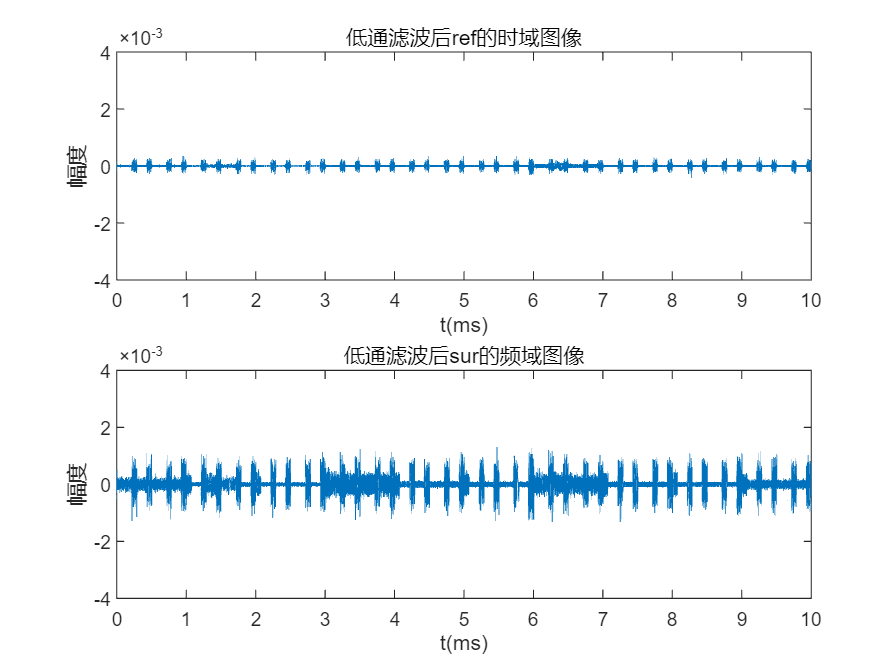

xlabel('t(ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);
title('低通滤波后sur的频域图像');

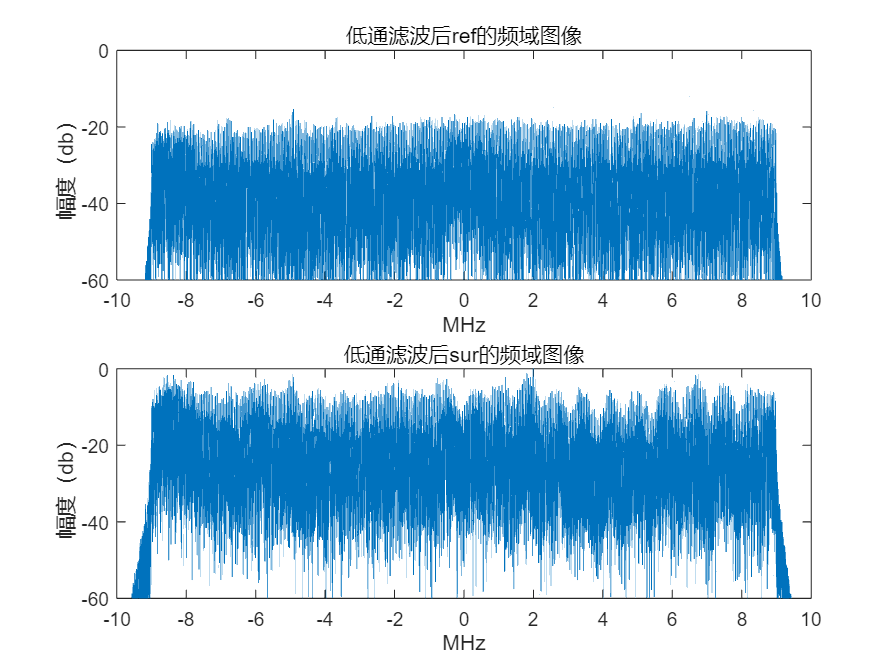

% 画出经过低通滤波的频谱图像
fft_ref = fft(ref_filter);
fft_sur = fft(sur_filter);
N = length(fft(ext_ref));
%频谱横坐标
f1 = (-(N-1)/2:(N-1)/2)*f_s/(N*10^6);
%频谱纵坐标
magnitude_ref=20 * log10(abs(fft_ref));
magnitude_sur=20 * log10(abs(fft_sur));
fftshift_magnitude_ref = fftshift(20 * log10(abs(fft_ref)));
fftshift_magnitude_sur = fftshift(20 * log10(abs(fft_sur)));
figure;
subplot(2,1,1)
plot(f1,fftshift_magnitude_ref);
ylim([-60 0]);
title('低通滤波后ref的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

subplot(2,1,2)
plot(f1,fftshift_magnitude_sur);
ylim([-60 0]);
title('低通滤波后sur的频域图像');
xlabel('MHz');
ylabel('幅度（db）');